# Landing a Probe on Mars

Instructions are in the task pane to the left. Complete and submit each task one at a time. 

## Task 1

Find and plot the probe's velocity.

*Remember to define your ODE function at the bottom of this script.*

The velocity *v* of a probe falling towards Mars is governed by the differential equation

*d**v/d**t*=*g*−*D**v^*2

where *D*=3.3×10−5 m-1, *g*=3.72 m/s2, *v* is in m/s, and *t*

 is in seconds. The probe enters the atmosphere with an initial velocity of 6 km/s (6000 m/s)

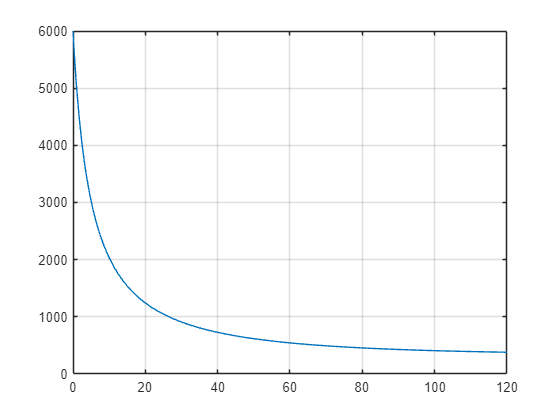

tRange = [0 120];
v0 = 6000;
[tSol, vSol] = ode45(@fallingbody, tRange, v0);
plot(tSol, vSol)
grid on

## Task 2

v120 = vSol(end)

v120 = 380.6347

## Task 1 (continued)

Define the ODE function to solve    with *D* = `3.3e-5` and *g* = `3.72`. 

function dvdt = fallingbody(t, v)
    D = 3.3e-5;
    g = 3.72;
    dvdt = g - D*v^2;
end